% Verify format 
K=13.86;%29.66;%18.08;%34.47;%15; %20.46;%1.4;%3
T=0.0002648;%0.03266;%0.08224;%0.08099;%0.15;%0.03573;%0.7;%0.1
Gp=tf(K,[T 1 0]);

Kp = 12.114592

Kp = 12.1146

Kd = 0

Kd = 0

Ki = 0

Ki = 0

PID=pid2(Kp,Ki,Kd);
Solution.M=feedback(PID*Gp,1);

Error using InputOutputModel/feedback
The first and second arguments of the "feedback" command must have compatible I/O sizes.

% Plot of the response when the input is a step, useful when designing with
% the error of the step response
figure(1);
step(Solution.M,0:0.05:5);


## Motor 1

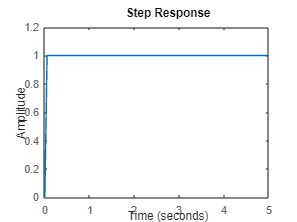

% Seleccionar un solo valor de K y T
K = 13.86;  % Usando el primer valor
T = 0.0002648;  % Usando el primer valor

% Crear la función de transferencia
Gp = tf(K, [T 1 0]);

% Parámetros del PID
% Kp1 = 12.114592;
% Kd1 = 0;
% Ki1 = 0;
% ----
% bestmem: [11.8483 0.1859 0.0039]
%          error: 0.2149
% -----
Kp1 = 11.848337;
Kd1 = 0.185874;
Ki1 = 0.003900;

% Crear el controlador PID
% En lugar de pid2, usar tf para crear la función de transferencia del PID
C = tf([Kd1 Kp1 Ki1], [1 0]);  % Forma: Kd*s + Kp + Ki/s

% Crear el sistema en lazo cerrado
Solution.M = feedback(C*Gp, 1);

% Graficar la respuesta al escalón
figure(1);
step(Solution.M, 0:0.05:5);

## Motor 2

% Parámetros del PID
Kp2 = 12.114592;
Kd2 = 0;
Ki2 = 0;

% Crear el controlador PID
% En lugar de pid2, usar tf para crear la función de transferencia del PID
C = tf([Kd1 Kp1 Ki1], [1 0]);  % Forma: Kd*s + Kp + Ki/s

% Crear el sistema en lazo cerrado
Solution.M = feedback(C*Gp, 1);

% Graficar la respuesta al escalón
figure(1);
step(Solution.M, 0:0.05:5);